ANDREA RODRIGUEZ MORENO

# TALLER 15

**OBJETIVO**

- Resolver numéricamente, aplicando el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado no lineal de un péndulo simple con fuerza tangencial.

**INTRODUCCIÓN**

En el presente taller nos enfocaremos en la formulación, resolución y representación gráfica de una ecuación no lineal de segundo orden que modela un péndulo simple bajo la influencia de una fuerza tangencial. Emplearemos el método Runge-Kutta a través de la función ode45 y en los 10 puntos se observarán los efectos de la modificación de sus variables y demás consideraciones en el sistema.

**METOLOGIA**

- Elementos teóricos de lo visto en clase.

- Métodos analíticos, deductivos y simbolicos.

- Ejercicios experimentales.

- Uso del sotfware Matlab.

**MODELO**

                                       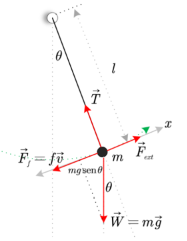         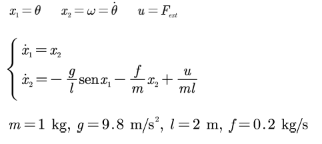

**ACTIVIDADES**

- Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

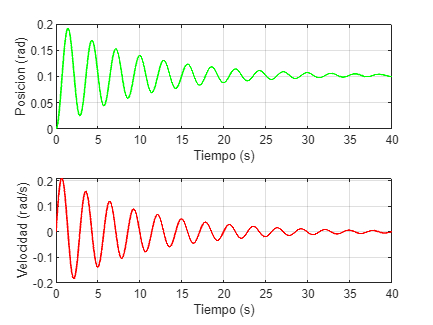

%Variables simbolicas
syms x1(t) x2(t)

%Parametros 
m = 1;                                          % Masa               
g = 9.8;                                        % Gravedad                           
l = 2;                                          % Longitud de la cuerda            
u = 1;                                          % Fuerza externa                  
f = 0.2;                                        % Coeficiente de friccion viscosa                                           

%Ecuaciones del modelo de un pendulo simple
f1 = x2;                                        
f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));         

funcion = odeFunction([f1 f2],[x1 x2]);

% Parametros para el metodo numerico
h1 = 0.01;                    
intervalo = 0:h1:100;             
ci = [0,0];                     

% Solucion 
[t, sol] = ode45(funcion,intervalo,ci);

%información del grafico
figure
x1 = sol(:,1); 
x2 = sol(:,2);
subplot(2,1,1)
plot(t,x1,"Color","g", "LineWidth", 1.2), xlabel("Tiempo (s)"), ylabel("Posicion (rad)"), grid on
xlim([0 40])
subplot(2,1,2)
plot(t,x2,"Color","r", "LineWidth", 1.2), xlabel("Tiempo (s)"), ylabel("Velocidad (rad/s)"), grid on
xlim ([0 40])

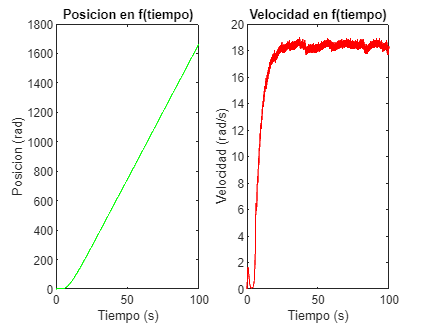

% ESTE CODIGO ES PARA PODER HALLAR E INTERPRETAR EL VALOR MAXIMO QUE HACE
% QUE EL SISTEMA ROTE INDEFINIDAMENTE
syms x1(t) x2(t)
syms x1p x2p

%Parametros 
m = 1;                                           
g = 9.8;                                            
l = 2;                                          
u = 7.55;                                  
f = 0.2;                                                         

%Ecuaciones del modelo
f1 = x2;                                        
f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));         

F = [x2p==0;
    (-g/l)*sin(x1p)-(f/m)*x2p + u/(m*l)==0;];

Equilibriossym = solve(F);

Equilibriossym.x1p;
Equilibriossym.x2p;


funcion = odeFunction([f1 f2], [x1 x2]);

% Parametros para el metodo numerico
h1 = 0.01;                                       % Tamaño del paso 
intervalo = 0:h1:100;                            % Intervalo de tiempo    
ci = [0,0]; 

% Solucion 
[t, sol] = ode45(funcion,intervalo,ci);

%informacion del grafico
figure
x1 = sol(:,1);
x2 = sol(:,2);
T = sin(x1)*m*g;
grid on

subplot(1,2,1);
plot(t,x1, 'Color', 'g');
xlabel("Tiempo (s)");
ylabel("Posicion (rad)");
title("Posicion en f(tiempo)")

subplot(1,2,2); 
plot(t,x2, 'Color', 'r');
xlabel("Tiempo (s)");
ylabel("Velocidad (rad/s)");
title("Velocidad en f(tiempo)")

**ANALISIS**

A partir del primer codigo, se infiere que:

En ambos gráficos, se aprecia que la amplitud disminuye gradualmente hasta que el sistema se estabiliza, esto se debe a la presencia de fricción  que disipa la energía progresivamente hasta que el sistema alcance el equilibrio; La gráfica de velocidad, se nota que la amplitud máxima ocurre cerca de $0\ldotp 2\;\frac{\textrm{rad}}{s}$, y el mínimo se alcanza en  $-\;0\ldotp 2\;\frac{\textrm{rad}}{s}$ , lo cual se da por el cambio de dirección en el movimiento; La grafica de posicion, se puede identificar un valor máximo que se alcanza aproximadamente en $0\ldotp 2\;\textrm{rad}$. Además, teniendo en cuenta que se aplica un ángulo inicial, el sistema oscila en torno a un eje diferente al cero, el cual tiene un valor aproximado de $0\ldotp 1\;\textrm{rad}$.

A partir del segundo codigo, se infiere que:

El valor que hace que el péndulo rote infefinidamente en circulos es de una fuerza externa de ** 7.55N**, para números menores a este el péndulo oscila y para valores superiores a este el péndulo gira indefinidamente. Por lo que el valor máximo de la entrada que hace que el sistema rote indefinidamente es de u = 7.55.

**2.  **Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

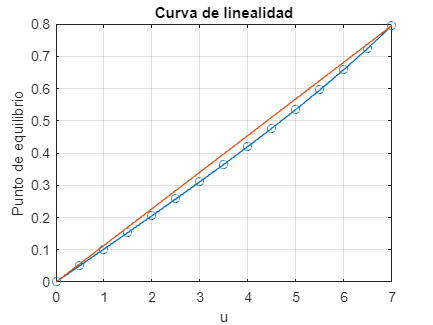

% Se definen las variables simbolica.
syms x1(t) x2(t)

% parametros.
m = 1; g = 9.8; l = 2; f = 0.2; 

% ecuaciones.
f1 = x2;
%(de min a max en avances h).
Input = 0:0.5:7;
tspan = 0:0.1:100;

% condiciones iniciales.
ci = [0 0];


x1L = zeros(1, length(Input));
for i = 1:length(Input)
    u = Input(i);
    %ecuaciones.
    f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));
    fun = odeFunction([f1 f2],[x1 x2]);
    % Aplicación del método numérico de Runge-Kutta
    [~,sol] = ode45(fun,tspan,ci);
    % Definición de la solución de las ecuación.
    x1L(i) = sol(end, 1);
end
%informacion del grafico
figure
plot(Input,x1L,'o-')
hold on
plot([0 Input(end)],[0 x1L(end)])
title ('Curva de linealidad')
xlabel('u')
ylabel('Punto de equilibrio')
grid on

**ANALISIS**

La figura anterior ilustra el rendimiento del sistema en relación a la fuerza que se le aplica. En este gráfico, se observa cómo estos dos parámetros muestran una evaluación lineal, lo que significa que un aumento en la fuerza aplicada resulta en un aumento en la posición. Ademas, es importante que dentro de este rango de fuerzas, el sistema siempre regresa a un punto de equilibrio, ya que no se supera el valor de entrada que haría que el sistema oscilara de forma indefinida.

**3. **Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

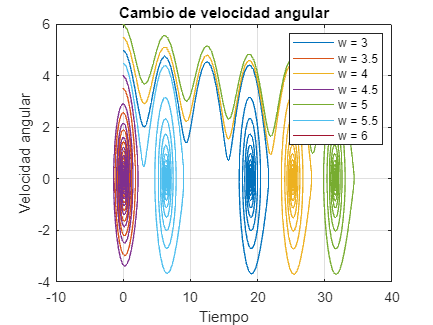

%variables simbolicas
syms x1(t) x2(t)
% Definición de parametros.
m = 1; g = 9.8; l = 2; f = 0.2;  u = 1;

%ecuiaciones
f1 = x2;
f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));
fun = odeFunction([f1 f2],[x1 x2]);

x20 = 3:0.5:6;
tspan = 0:0.1:100;

% informacion del grafico
figure
for i = 1:length(x20)
    %condiciones iniciales.
    ci = [0 x20(i)];
    %Solución del método numérico y aplicación del método numérico de Runge-Kutta
    [~,sol] = ode45(fun,tspan,ci);
    plot(sol(:,1),sol(:,2));
    plot(0, x20(i))
    hold on
end
title('Cambio de velocidad angular')
xlabel('Tiempo')
ylabel('Velocidad angular')
legend({'w = 3','w = 3.5', 'w = 4','w = 4.5', 'w = 5', 'w = 5.5', 'w = 6'},'location','best')
grid on

**ANALISIS**

Por medio de la gráfica, las tendencias de color representan ciclos, con la frecuencia angular inicial de 4.5 para una vuelta y de 5 para tres vueltas, estabilizándose en su punto de equilibrio. Para otras trayectorias, frecuencias angulares de 3.5 y 4 se aproximan rápidamente a su equilibrio. La cuarta trayectoria, con frecuencia angular de 5.5, completa 4 vueltas, y la quinta, con frecuencia angular de 6, da 5 vueltas. **Mayor velocidad angular implica más vueltas del péndulo.**

**4. **Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

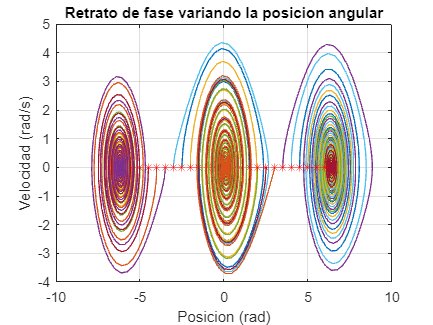

% se declaran variables simbolicas
syms x1(t) x2(t)

%Parametros
m = 1;                                          % Masa del sistema                   
g = 9.8;                                        % Gravedad                               
l = 2;                                          % Longitud de la cuerda            
u = 1;                                          % Fuerza externa                   
f = 0.2;                                        % Coeficiente de friccion viscosa  
           

%Ecuaciones del modelo pendulo simple
f1 = x2;                                    
f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));         

funcion = odeFunction([f1 f2],[x1 x2]);

%Para metodo numerico
X20 = -6:0.5:6;                                 
h = 0.1;                                        
intervalo = 0:h:100;

%informacion del grafico
figure 
for i = 1:length(X20)
    ci = [X20(i) 0];
    [~, sol] = ode45(funcion, intervalo, ci);
    plot(sol(:,1), sol(:,2))
    hold on
    plot(X20(i), 0, 'r*')
end
xlabel('Posicion (rad)')
ylabel('Velocidad (rad/s)')
title("Retrato de fase variando la posicion angular")
grid on 

**ANALISIS**

En el punto de equilibrio central, el sistema oscila en un rango de $-2\;\textrm{rad}$ hasta $2\;\textrm{rad}$. La velocidad aumenta a medida que se completan las vueltas debido al movimiento en diferentes direcciones, tanto hacia arriba como hacia abajo, lo que crea una espiral en las gráficas de posición y velocidad. 

En la gráfica izquierda, se muestra un comportamiento similar al punto de equilibrio central, pero con una disminución de la velocidad y en la gráfica de la derecha, la velocidad aumenta a medida que el sistema oscila en dos direcciones, pero no se suelta en un ángulo negativo.

**5.  **Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

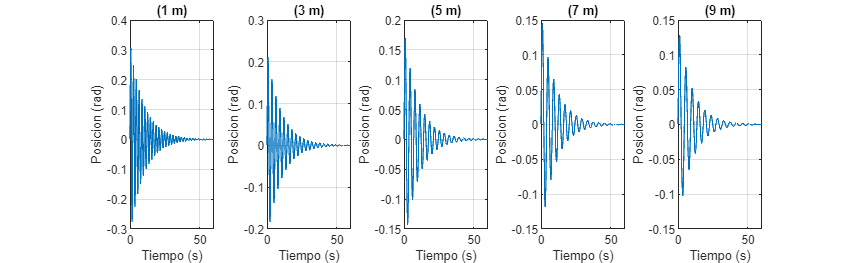

syms x1(t) x2(t)
%Parametros
m = 1;                                          % Masa del sistema                 (kg)  
g = 9.8;                                        % Gravedad                         (m/s^2)      
l = [1 3 5 7 9];                                % Longitud de la cuerda            (m)
u = 1;                                          % Fuerza externa                   (N)
f = 0.2;                                        % Coeficiente de friccion viscosa  (kg/s)                                         
           
%Ecuaciones del modelo 
f1 = x2;                                        % Ecuacion 1

%Parametros para el metodo numerico
h = 0.1;                                        % Tamaño del paso
intervalo = 0:h:60;                             % Intervalo

ci = [0 0];                                     % Condiciones iniciales

h1 = figure;
for l_i = 1: length(l)
    f2 = -(g/l_i)*sin(x1)-(f/m)*x2+(u/(m*l_i)); % Ecuacion 2 
    funcion = odeFunction([f1 f2],[x1 x2]);
    [t,x] = ode45(funcion,intervalo,ci);
    subplot(1,5,l_i)  
    plot(t,x(:,2))
    xlabel('Tiempo (s)')
    ylabel('Posicion (rad)')
    grid on 
    title(['(', num2str(l(l_i)),' m)'])
end

set(h1,'Units','normalized','Position',[0 0 1 0.5]); 

**ANALISIS**

Con las condiciones inciales iguales a 0, el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1, se da que para péndulos con diferentes longitudes (1 a 9m), se observa que las oscilaciones muestran comportamientos distintos. Cuanto más larga sea la cuerda, las oscilaciones son más lentas, lo que se traduce en movimientos suaves y menos pronunciados, como se muestra en la gráfica. Por otro lado, con cuerdas más cortas, las oscilaciones son más rápidas, lo que resulta en una mayor cantidad de oscilaciones en un período de tiempo.

Independientemente de la longitud de la cuerda, todos los péndulos alcanzan la estabilización en el mismo tiempo, lo que constituye un hecho universal.

**6.  **Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

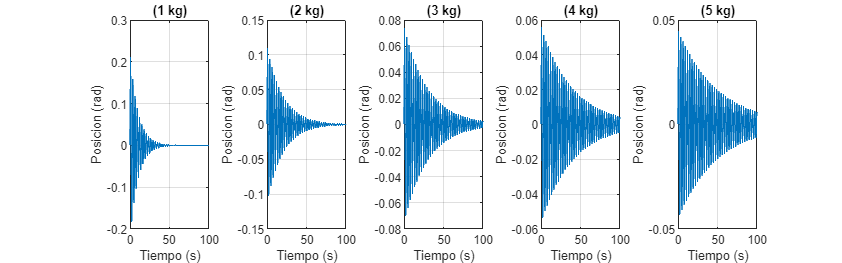

%se declaran variables simbolicas
syms x1(t) x2(t)
% Parametros
m = [ 1 2 3 4 5];                              % Masa                              
g = 9.8;                                        % Gravedad                               
l = 2;                                          % Longitud de la cuerda            
u = 1;                                          % Fuerza externa                   
f = 0.2;                                        % Coeficiente de friccion viscosa  
                      
% Ecuaciones del modelo 
f1 = x2;                                       

% Parametros para el metodo numerico
h = 0.1;                                        % Tamaño del paso
intervalo = 0:h:100;
ci = [0 0];                                     % Condiciones iniciales

%Solucion grafica por metodo numerico
h1 = figure;
for m_i = m
    f2 = -(g/l)*sin(x1)-(f/m_i)*x2+(u/(m_i*l)); 
    funcion = odeFunction([f1 f2],[x1 x2]);
    [t,x] = ode45(funcion,intervalo,ci);
    subplot(1,5,m_i)  
    plot(t,x(:,2))
    xlabel('Tiempo (s)')
    ylabel('Posicion (rad)')
    grid on 
    title(['(', num2str(m_i),' kg)'])
end

set(h1,'Units','normalized','Position',[0 0 1 0.5]);

**ANALISIS**

se explora cómo el sistema se comporta ante cambios en la masa, a empaquetando un rango desde un valor 1kg de masa hasta un valor 5kg. De las gráficas, se aprecia que el tiempo requerido para que el sistema alcance la estabilización presenta variaciones notables. Esta variabilidad está ligada al aumento de la amplitud que se observa conforme se incrementa la masa. La causa de este comportamiento radica en el hecho de que una masa mayor ejerce una fuerza más significativa al interactuar con la gravedad. Como se ha analizado, la fuerza y ��la posición mantienen una relación directa y, por lo tanto, influyen en el tiempo que se necesita para que el sistema alcance su equilibrio.

**7. **Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

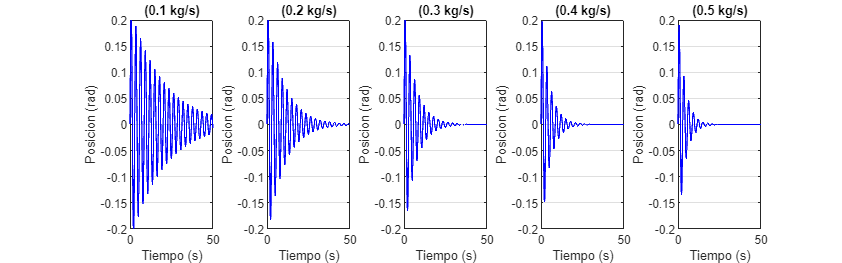

syms x1(t) x2(t)
% Parametros
m = 1;                                          % Masa                                
g = 9.8;                                        % Gravedad                               
l = 2;                                          % Longitud de la cuerda            
u = 1;                                          % Fuerza externa                   
f = [0.1 0.2 0.3 0.4 0.5];                      % Coeficiente de friccion viscosa  
                      
% Ecuaciones del modelo 

f1 = x2;                                        

% Parametros para el metodo numerico
h = 0.1;                                        % Tamaño del paso
intervalo = 0:h:100;
ci = [0 0];                                     % Condiciones iniciales

%Solucion grafica por metodo numerico
h1 = figure;
for f_i = f
    f2 = -(g/l)*sin(x1)-(f_i/m)*x2+(u/(m*l)); % Ecuacion 2
    funcion = odeFunction([f1 f2],[x1 x2]);
    [t,x] = ode45(funcion,intervalo,ci);
    subplot(1,5,(f_i*10))  
    plot(t,x(:,2), "Color","g", "Color","b")
    xlabel('Tiempo (s)')
    xlim([0 50])
    ylabel('Posicion (rad)')
    ylim([-0.2 0.2])
    grid on 
    title(['(', num2str(f_i),' kg/s)'])
end

set(h1,'Units','normalized','Position',[0 0 1 0.5]);

**ANALISIS**

Al considerar los péndulos con diferentes niveles de fricción viscosa (0.1,  a 0.5), se observa que las oscilaciones se comportan de manera distinta. A medida que la fricción aumenta, las oscilaciones se vuelven más lentas, lo que se traduce en movimientos menos intensos y notorios. La fricción actúa como una resistencia al movimiento, lo que limita la cantidad y duración de las oscilaciones del péndulo. Esto contribuye a que el péndulo alcance la estabilización en el sistema de manera más rápida.

En la gráfica, se puede notar que el péndulo con mayor fricción de 0.5 kg/s muestra una amplitud menor en comparación con los demás y se estabiliza más rápidamente hacia su punto de equilibrio debido a la mayor oposición al movimiento que enfrenta.

**8. **Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB.

syms x(t)

d1 = diff(x,t,1);
d2 = diff(x,t,2);

Ecuacion = d2 + 4.900*x == 0;

c_1 = x(0) == pi/12;
c_2 = d1(0) == 0;

Solucion = dsolve(Ecuacion,c_1,c_2)

$$Solucion = \frac{\pi \,\cos\left(\frac{7\,\sqrt{10}\,t}{10}\right)}{12}$$

**Solución analítica:**


$$\begin{array}{l}
x_1 =\theta \\
x_{2\;} =\dot{\theta} 
\end{array}$$
 
$$\Longrightarrow$$

$$\begin{array}{l}
\dot{x_1 } =x_2 \\
\dot{x_2 } =-\frac{g}{l}{*\;x}_1 
\end{array}$$


Entonces,

$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{l} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \;$;   $X_0 =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$

Se concidera que $u=0$ y $f=0$, $\theta \left(0\right)=\frac{\Pi }{12}$ o sea 15°

$\ddot{\theta} +\frac{g}{l}=0$;      $d=-4\frac{g}{l}\Longrightarrow d<0$


$$\theta =e^0 \lbrack c_1 \;\textrm{sen}\left(\frac{\sqrt{4\frac{g}{l}}}{2}t\right)+c_2 \;\cos \left(\frac{\sqrt{4\frac{g}{l}}}{2}t\right)\rbrack$$


Como $\theta \left(0\right)=\frac{\Pi }{12}\Longrightarrow c_1 =\frac{\Pi }{12}$ 

Ahora, como $\dot{\theta} \left(0\right)=0\Longrightarrow c_{2\;} =0$


$$\theta \left(t\right)=\frac{\Pi }{12}\cos \left(\frac{\sqrt{4\frac{g}{l}}}{2}t\right)$$



$$\frac{g}{l}=4\ldotp 9$$


**ANALISIS**

Comprobando con MATLAB y ademas de resolver analiticamente, se infiere que cuando se utiliza un ángulo inicial menor de 30° y en este caso fue de 15°, el sistema se simplifica. Además, al tener conocimiento de la solución para el sistema, es posible determinar tanto la gravedad como la longitud del péndulo, por lo tanto, si se tiene información acerca de uno de estos parámetros, se puede calcular por medio de el modelo el otro parametro con facilidad.

**9. **Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7

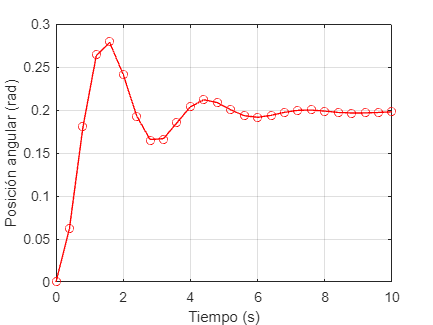

syms theta(t) w(t)
%Parametros
m = 0.52;                                       % Masa por tanteo                                 
g = 9.8;                                        % Gravedad                                         
l = 2;                                          % Longitud de la cuerda                       
u = 1;                                          % Fuerza externa                              
f = 0.6;                                        % Coeficiente de friccion viscosa por tanteo  
theta1= [0                                      % Posicion angular                    
0.0621
0.1797
0.2635
0.2783
0.2414
0.1932
0.1656
0.1667
0.1852
0.2038
0.2119
0.2086
0.2002
0.1934
0.1915
0.1938
0.1973
0.1997
0.1999
0.1987
0.1972
0.1965
0.1966
0.1972
0.1978];

% Ecuaciones del modelo 
f1 = x2;                                     
f2 = -(g/l)*sin(x1)-(f/m)*x2+(u/(m*l));       
funcion = odeFunction([f1 f2],[x1 x2]);

% Parametros para el metodo numerico
h = 0.4;                                      
intervalo = 0:h:10;
%Condiciones iniciales
ci = [0 0];                                  

%Solucion grafica por metodo numerico
[t,x] = ode45(funcion,intervalo,ci);

%informacion del grafico
figure
plot(t, x(:,1), 'o', t, theta1, "color", "r");
xlabel('Tiempo (s)')
ylabel('Posición angular (rad)')
grid on 

**ANALISIS**

Para este punto, se usa la prueba y error para encontrar la combinación adecuada de masa y coeficiente de fricción que sea analogo al movimiento deseado del sistema. La masa incide directamente en la amplitud del movimiento: una masa mayor que $0\ldotp 5\;\mathrm{kg}$ aumenta la amplitud de la gráfica de posiciones en comparación con las posiciones iniciales, mientras que una masa menor disminuye esta amplitud. Por otro lado, el coeficiente de fricción afecta el tiempo de estabilización del sistema. Un coeficiente de fricción mayor provoca que los puntos en la gráfica se dispersen, lo que indica menos oscilaciones en comparación con la gráfica original. Un coeficiente de fricción menor agrupa los puntos de manera que se observan más oscilaciones que en la gráfica original.

***Los analisis en cada ejercicio hacen referencia a la discusion de los resultados.***